# 2 DoF Platform

Author: Emerson Kaneda

data = readtable("10_07_2024_Pcontroller");
FontSize = 30;

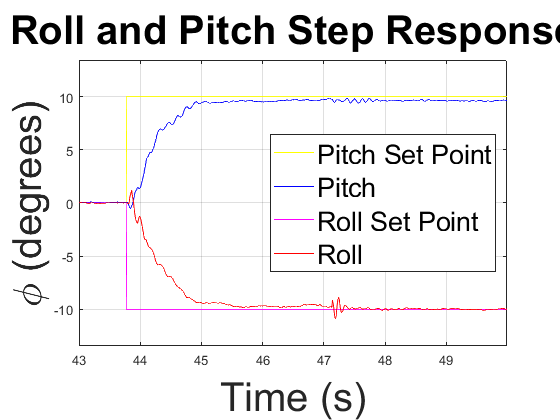


pitch = data.Pitch;
roll = data.Roll;
pitch_set_point = data.Pitch_set_point;
roll_set_point = data.Roll_set_point;

time = (0:length(pitch)-1) * 0.01; % 0.01 segundos = 10 ms
start_time = 43;
% start_time = 25;

figure;
plot(time, pitch_set_point, 'y', 'DisplayName', 'Pitch Set Point');
hold on;
plot(time, pitch, 'b', 'DisplayName', 'Pitch');
plot(time, roll_set_point, 'm', 'DisplayName', 'Roll Set Point');
plot(time, roll, 'r', 'DisplayName', 'Roll');
hold off;

% Adicionar título e legendas
title('Roll and Pitch Step Response','FontSize', FontSize);
xlabel('Time (s)','FontSize', FontSize);
ylabel({'\phi (degrees)'},'FontSize', FontSize);
legend('show', 'Location', 'east','FontSize', 20);
% legend('show', 'Location', 'southwest','FontSize', 20);
grid on;

xlim([start_time, time(end)]);
% Exibir o gráfico
ylim([-max(max(abs([pitch; roll; pitch_set_point; roll_set_point])))*1.1, ...
    max(max(abs([pitch; roll; pitch_set_point; roll_set_point])))*1.1]);

highlight_time = 47.21; % Tempo em segundos a ser destacado
highlight_roll = roll(find(time >= highlight_time, 1)); % Valor de pitch nesse tempo
hold on;
% plot(highlight_time, highlight_roll, 'ro', 'MarkerSize', 30, 'LineWidth', 2,"DisplayName","Mechanical Noise","Color","k"); % Destacar o ponto com um círculo
hold off;


% Definição das constantes
L1 = 70;
L2 = 200;
hCentral = sqrt(L2^2 - L1^2)

hCentral = 187.3499

d = 200;

% Definição do intervalo de theta
theta = -90:1:90;
% Cálculo de h
h = L1 * sind(theta) + sqrt(L2^2 - (L1* cosd(theta)).^2)

h =   130.0000  130.0069  130.0277  130.0624  130.1109  130.1733  130.2496  130.3397  130.4438  130.5618  130.6937  130.8396  130.9994  131.1732  131.3611  131.5629  131.7788  132.0088  132.2528  132.5110  132.7834  133.0699  133.3706  133.6856  134.0149  134.3584  134.7163  135.0886  135.4753  135.8763  136.2919  136.7220  137.1666  137.6257  138.0994  138.5878  139.0908  139.6085  140.1408  140.6879  141.2498  141.8264  142.4178  143.0239  143.6449  144.2807  144.9314  145.5969  146.2772  146.9723


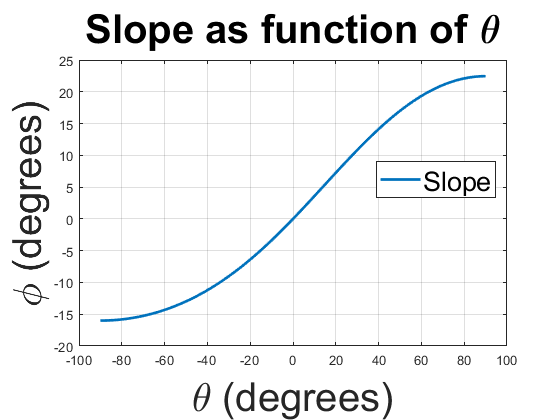

slope = atand((h - hCentral)/d);


% Plot do gráfico
figure;
plot(theta, slope, 'LineWidth', 2);
title('Slope as function of \theta','FontSize', FontSize);
xlabel('\theta (degrees)','FontSize', FontSize);
ylabel('\phi (degrees)','FontSize', FontSize);
legend('Slope ', 'Location', 'best','FontSize', 20);
grid on;

% Carregar os dados
pitch = data.Pitch;
roll = data.Roll;
pitch_set_point = data.Pitch_set_point;
roll_set_point = data.Roll_set_point;

% Tempo entre amostras
dt = 0.01; % Intervalo de tempo entre as amostras em segundos
time = 0:dt:dt*(length(pitch)-1);

% Ignorar dados antes de 43 segundos
start_time = 43;
start_idx = find(time >= start_time, 1);

steady_state_time = 5; % em segundos
steady_state_idx = find(time >= steady_state_time, 1);

pitch = pitch(start_idx:end);
roll = roll(start_idx:end);
pitch_set_point = pitch_set_point(start_idx:end);
roll_set_point = roll_set_point(start_idx:end);
time = time(start_idx:end) - start_time;

% Calcular parâmetros para pitch
[tr_pitch, ts_pitch, type_pitch, ess_pitch] = analyze_response(pitch, pitch_set_point, time, 0.02, steady_state_idx);

% Calcular parâmetros para roll
[tr_roll, ts_roll, type_roll, ess_roll] = analyze_response(roll, roll_set_point, time, 0.02, steady_state_idx);

% Exibir resultados
fprintf('Pitch - Tempo de Subida: %.2f s\n', tr_pitch);

Pitch - Tempo de Subida: 0.83 s


fprintf('Pitch - Tempo de Assentamento: %.2f s\n', ts_pitch);

Pitch - Tempo de Assentamento: 4.75 s


fprintf('Pitch - Tipo de Amortecimento: %s\n', type_pitch);

Pitch - Tipo de Amortecimento: Criticamente Amortecido (Critically Damped)


fprintf('Pitch - Erro em Regime Permanente: %.4f\n', ess_pitch);

Pitch - Erro em Regime Permanente: 0.3746



fprintf('Roll - Tempo de Subida: %.2f s\n', tr_roll);

Roll - Tempo de Subida: 0.91 s


fprintf('Roll - Tempo de Assentamento: %.2f s\n', ts_roll);

Roll - Tempo de Assentamento: 6.99 s


fprintf('Roll - Tipo de Amortecimento: %s\n', type_roll);

Roll - Tipo de Amortecimento: Subamortecido (Under-damped)


fprintf('Roll - Erro em Regime Permanente: %.4f\n', ess_roll);

Roll - Erro em Regime Permanente: 0.0394


function [tr, ts, type, ess] = analyze_response(response, set_point, time, tol, ss_idx)
    % Normalizar resposta
    norm_response = response - set_point(1);
    norm_response = norm_response / (set_point(end) - set_point(1));

    % Tempo de subida (10% a 90%)
    idx_10 = find(norm_response >= 0.1, 1);
    idx_90 = find(norm_response >= 0.9, 1);
    tr = time(idx_90) - time(idx_10);

    % Tempo de assentamento
    final_value = set_point(end);
    idx_ts = find(abs(response - final_value) <= tol*abs(final_value), 1, 'last');
    ts = time(idx_ts);

    % Tipo de amortecimento
    overshoot = max(response) - final_value;
    if overshoot > tol * abs(final_value)
        type = 'Subamortecido (Under-damped)';
    elseif overshoot < tol * abs(final_value) && overshoot > 0
        type = 'Superamortecido (Over-damped)';
    else
        type = 'Criticamente Amortecido (Critically Damped)';
    end

    % Erro em regime permanente
    ess = abs(response(ss_idx:end) - final_value);
    ess = mean(ess); % Média do erro após o tempo de regime permanente
end